# **FORÅR 2018 REEKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

**En kontinuert stokastisk variabel X har følgende cdf.**

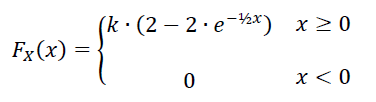

## **1.1 GYLDIG FORDELINGSFUNKTION**

For at bestemme for hvilken værdi af $k$ at $F_X \left(x\right)$ er en gyldig tæthedsfunktion anvendes, at


$$\lim_{x\to \infty } F_X \left(x\right)=1$$



$$\lim_{x\to \infty } k\cdot \left(2-2\cdot e^{-\frac{1}{2}x} \right)=1$$


syms Fx(x) k

Fx(x) = piecewise(x >= 0, (k*(2-2*exp((-1/2)*x))), 0);
k = solve(limit(Fx(x), x, inf) == 1, k)

$$k = \frac{1}{2}$$

$F_X \left(x\right)$er en gyldig fordelingsfunktion for værdien af $k=\frac{1}{2}$. 

## **1.2 TÆTHEDSFUNKTION**

For at bestemme tæthedsfunktionen $f_X \left(x\right)$ anvendes, at


$$f_X \left(x\right)=\frac{\textrm{d}}{\textrm{d}x}F_X \left(x\right)$$


diff(Fx(x))

$$ans = \left\{ \begin{array}{cl} k\,{\mathrm{e}}^{-\frac{x}{2}} & \text{ if }0<x\\ 0 & \mathrm{otherwise} \end{array}\right.$$

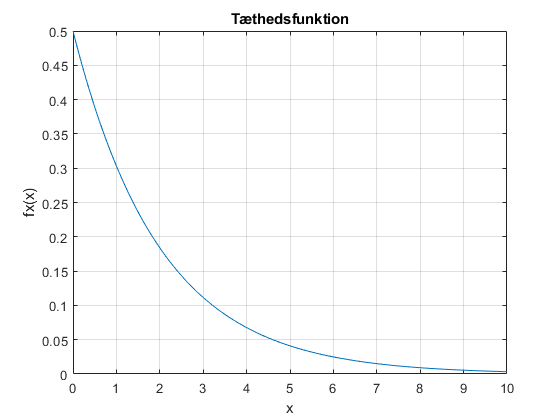

syms fx(x)

fx(x) = piecewise(x>=0, k*exp(-(x/2)), 0);

x = 0:0.01:10;

figure(1)
plot(x, fx(x));
title('Tæthedsfunktion')
xlabel('x')
ylabel('fx(x)')
grid on

Den stokastiske variabels tæthedsfunktion er bestemt til at være den ovenstående som også er skitseret.

## **1.3 SANDSYNLIGHED**

For at bestemme sandsynligheden for at den stokastiske variabel $X$har en værdi mellem 1 og 2 $P\left(1\le X\le 2\right)$anvendes, at


$$P\left(a\le X\le b\right)=\int_a^b f_X \left(x\right)\mathrm{dx}=F_X \left(b\right)-F_X \left(a\right)$$


syms fx(x)
fx(x) = piecewise(x>=0, k*exp(-(x/2)), 0);

a = 1;
b = 2;

Probability = double(int(fx(x), a, b))

Probability = 0.2387

Sandsynligheden for at den stokastiske variabel $X$ har en værdi mellem 1 og 2 er bestemt til at være 0.2387 altså 23.87%.

## 1.4 MIDDELVÆRDI

For at bestemme middelværdien også kaldt forventningsværdien anvend, at


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$


syms fx(x)
f(x) = piecewise(x>=0, x*(k*exp(-(x/2))), 0);

EstimationValue = int(f(x), -inf, inf)

$$EstimationValue = 2$$

# **2 STOKASTISKE PROCESSER**

**En stokastisk proces er givet ved**

## **2.1 REALISERING**

Realiseringen er lavet i matlab med følgende kode.

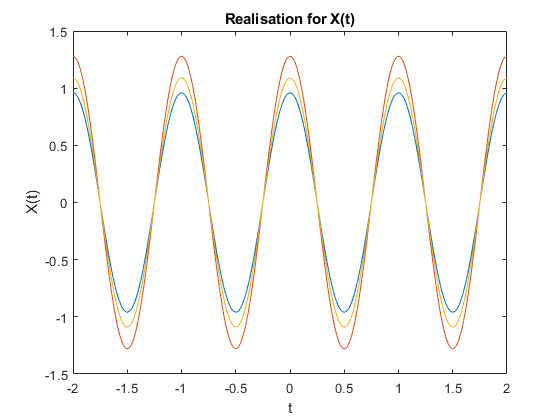

[a, b] = deal(0, 2);

A = a + (b-a) * rand(3, 1);

t = -2:0.01:2;

B = cos(2*pi*t);

X = A .* B;

figure(2)
plot(t, X)
title('Realisation for X(t)')
xlabel('t')
ylabel('X(t)')

Tre realiseringer er vist i ovenstående figure. 

## **2.2 TEMPORALE MIDDELVÆRDI OG VARIANS**

Den temporale middelværdi kan bestemmes som følgende


$$\hat{\mu_{X_i } } ={\left\langle X_i \right\rangle }_T =\underset{T\to \infty }{\mathrm{lim}} \frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x_i \left(t\right)\mathrm{dt}$$


Da arealet over og under en cosinus er lig med nul og vides altså at middelværdien er lig med nul. Set ud fra ovenstående udtryk ses at integralet af cosinus funktionen giver arelaet hvilket dermed er lig med nul.

syms T t

Eq = (1/T) * int(A*cos(2*pi*t), -(T/2), (T/2));

F = double(limit(Eq, T, inf))

F =      0
     0
     0


syms T t

Eq = (1/T) * int(((A*cos(2*pi*t)).^2) - 0^2 , -(T/2), (T/2));

F = double(limit(Eq, T, inf))

F =     0.4598
    0.8175
    0.5934


## **2.3**

# **3 STOKASTISKE PROCESSER**

## **3.1**

## **3.2**

## **3.3**

# **4 STATISTIK**

## **4.1**

## **4.2**

## **4.3**